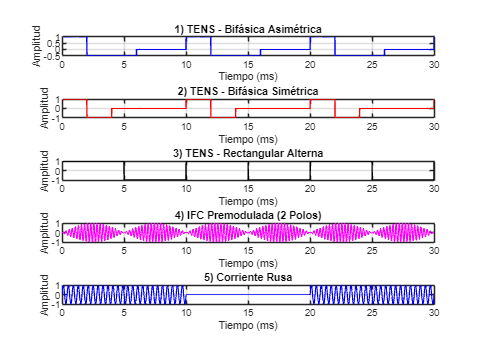

% --------------------------------------------------------
% ondas_electroterapia.m
% Ejemplo de graficación de 5 tipos de señales:
% 1) TENS Bifásica Asimétrica
% 2) TENS Bifásica Simétrica
% 3) TENS Rectangular Alterna
% 4) IFC Premodulada (2 polos)
% 5) Corriente Rusa
% --------------------------------------------------------

clear; clc; close all;

%% Parámetros generales
dt = 1e-5;          % Paso de tiempo (10 microsegundos)
t_total = 0.03;     % 30 ms de duración total para la mayoría de las señales
t = 0:dt:t_total;   % Vector de tiempo

% =========================================================
% 1) TENS - Bifásica Asimétrica
%    - Periodo: 10 ms
%    - Pulso positivo de 0 a 2 ms con amplitud +1
%    - Pulso negativo de 2 a 6 ms con amplitud -0.5
%    - Resto del periodo (6 a 10 ms) en 0
% =========================================================
T1 = 0.01; % 10 ms
t_mod_1 = mod(t, T1);
y1 = zeros(size(t));

idx_pos = (t_mod_1 >= 0    & t_mod_1 < 2e-3);  % 0 - 2 ms
idx_neg = (t_mod_1 >= 2e-3 & t_mod_1 < 6e-3);  % 2 - 6 ms
y1(idx_pos) = 1.0;
y1(idx_neg) = -0.5;

% Grafica
figure('Name','Ondas Electroterapia','NumberTitle','off');
subplot(5,1,1);
plot(t*1000, y1, 'b','LineWidth',1.2);
grid on;
xlabel('Tiempo (ms)');
ylabel('Amplitud');
title('1) TENS - Bifásica Asimétrica');
xlim([0 t_total*1000]);  % 0 a 30 ms

% =========================================================
% 2) TENS - Bifásica Simétrica
%    - Periodo: 10 ms
%    - Pulso positivo de 0 a 2 ms con amplitud +1
%    - Pulso negativo de 2 a 4 ms con amplitud -1
%    - Resto del periodo (4 a 10 ms) en 0
% =========================================================
T2 = 0.01; % 10 ms
t_mod_2 = mod(t, T2);
y2 = zeros(size(t));

idx_pos2 = (t_mod_2 >= 0    & t_mod_2 < 2e-3);  % 0 - 2 ms
idx_neg2 = (t_mod_2 >= 2e-3 & t_mod_2 < 4e-3);  % 2 - 4 ms
y2(idx_pos2) = 1.0;
y2(idx_neg2) = -1.0;

% Grafica
subplot(5,1,2);
plot(t*1000, y2, 'r','LineWidth',1.2);
grid on;
xlabel('Tiempo (ms)');
ylabel('Amplitud');
title('2) TENS - Bifásica Simétrica');
xlim([0 t_total*1000]);

% =========================================================
% 3) TENS - Rectangular Alterna
%    - Periodo: 10 ms
%    - Mitad del periodo en +1, mitad en -1
%    - No hay fase "apagada" (0 V)
% =========================================================
T3 = 0.01; % 10 ms
t_mod_3 = mod(t, T3);
y3 = zeros(size(t));
% Primera mitad del periodo
idx_pos3 = (t_mod_3 < T3/2);
% Segunda mitad del periodo
idx_neg3 = (t_mod_3 >= T3/2);

y3(idx_pos3) = 1.0;
y3(idx_neg3) = -1.0;

% Grafica
subplot(5,1,3);
plot(t*1000, y3, 'k','LineWidth',1.2);
grid on;
xlabel('Tiempo (ms)');
ylabel('Amplitud');
title('3) TENS - Rectangular Alterna');
xlim([0 t_total*1000]);

% =========================================================
% 4) IFC Premodulada (2 Polos)
%    - Frecuencia portadora alta, p.ej. 4000 Hz
%    - Frecuencia de modulación baja, p.ej. 100 Hz
%    - Se observa la "envolvente" de la señal portadora
% =========================================================
f_carrier = 4000; % Hz
f_mod = 100;      % Hz
% Para ver bien la modulación, se mantiene la misma ventana de 30 ms,
% pero si se quisiera mayor detalle, se podría aumentar la duración
y4 = sin(2*pi*f_carrier*t) .* sin(2*pi*f_mod*t);

% Grafica
subplot(5,1,4);
plot(t*1000, y4, 'm','LineWidth',1.0);
grid on;
xlabel('Tiempo (ms)');
ylabel('Amplitud');
title('4) IFC Premodulada (2 Polos)');
xlim([0 t_total*1000]);

% =========================================================
% 5) Corriente Rusa
%    - Frecuencia portadora ~2500 Hz
%    - Ráfagas (bursts) a 50 Hz con 50% de ciclo de trabajo
%    - Ej.: 10 ms ON, 10 ms OFF => 20 ms total (50 Hz)
% =========================================================
f_rusa = 2500;   % Frecuencia portadora
f_burst = 50;    % Frecuencia de ráfagas
T_burst = 1/f_burst;  % Periodo de ráfaga (20 ms)

t_mod_5 = mod(t, T_burst);
% Gate: encendido la mitad del periodo, apagado la otra mitad
gate = double(t_mod_5 < (T_burst/2));  
% Señal portadora
carrier_rusa = sin(2*pi*f_rusa*t);
% Señal rusa final
y5 = carrier_rusa .* gate;

% Grafica
subplot(5,1,5);
plot(t*1000, y5, 'b','LineWidth',1.0);
grid on;
xlabel('Tiempo (ms)');
ylabel('Amplitud');
title('5) Corriente Rusa');
xlim([0 t_total*1000]);


% --------------------------------------------------------
% Fin del script
% --------------------------------------------------------
